# Classify the Iris Dataset Using a Variational Quantum Classifier (VQC)

## Introduction

Quantum Machine Learning (QML) is an emerging research field that blends together two branches of computer science, quantum computing and machine learning. The main motivation behind QML is that quantum systems are proven to be able to rapresent and manipulate complex high-dimensional spaces more efficiently than classical computers can in certain scenarios [1][2]. This opens the possibility that one day QML could outperform classical ML, even if today's quantum computers are still very limited in scale and accuracy [3].  

In this example we are gonna build and train a simple VQC to solve a standard machine learning task, classifying 3 flower species from a dataset with 4 feature.

We build a hybrid quantum-classical neural network that includes:

- feature encoding into quantum rotations

- a trainable quantum layer based on parametrized gates and entangling operations

- the parameter-shift rule to compute gradients

- training via MATLAB's trainnet using the Adam optimizer.

### The dataset

The Iris dataset consists of 150 flowers samples from three species: Setosa, Versicolar and Virginica. It is widley used and a classic banckmark dataset for pattern recognition due to it's small size and the fact that one class is linearly separable from the others (Setosa) while the remaining two (versicolor and virginica) are not, making the problem non-trivial.

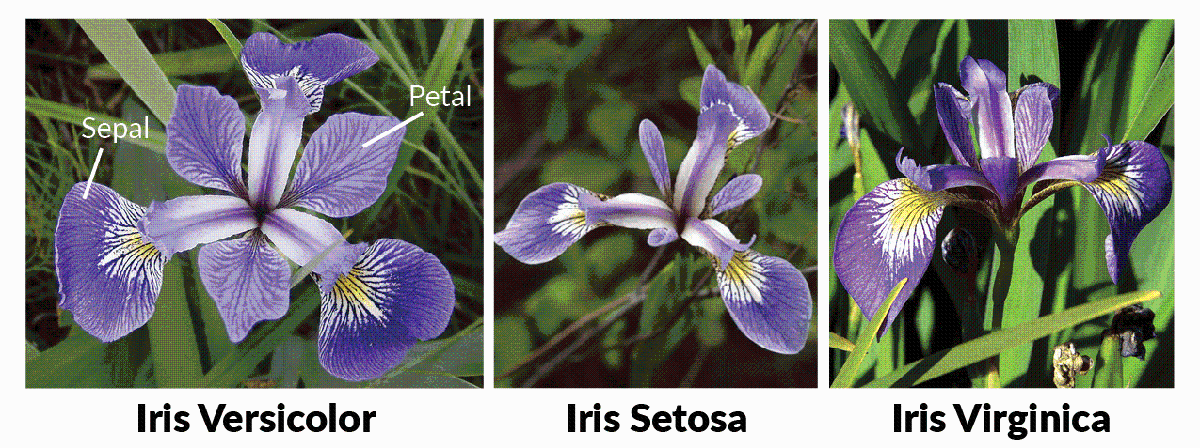

we can load the dataset directly

iris    = load('fisheriris');

each sample is described by four numerical features, sepal length (cm), sepal width (cm), petal length (cm) and petal width (cm).

these features form a 4-dimensonal input vector that can be used for multi-class classification

Xraw    = iris.meas;      % {'sepal.length','sepal.width','petal.length','petal.width'}
Yraw    = iris.species;   % {'setosa','versicolor','virginica'}

disp(array2table(Xraw(1:5,:), 'variableNames', {'sepal length', 'sepal width', 'petal length', 'petal width'}));

    sepal length    sepal width    petal length    petal width
    ____________    ___________    ____________    ___________

        5.1             3.5            1.4             0.2    
        4.9               3            1.4             0.2    
        4.7             3.2            1.3             0.2    
        4.6             3.1            1.5             0.2    
          5             3.6            1.4             0.2    



we now have to encode those feature in a quantum circuit by converting each feature into a rotation angle, to do so we rescale all features in the interval [$0-\pi$] allowing them to control rotation gates in a consistent way

% scale feature values into [0, 3.14] for quantum encoding
theta   = pi * rescale(iris.meas,0,1);

X = double(theta);                     % features 150 x 2
Y = categorical(Yraw);                 % classes  150 x 1

disp(array2table(X(1:5,:), 'variableNames', {'sepal length', 'sepal width', 'petal length', 'petal width'}));

    sepal length    sepal width    petal length    petal width
    ____________    ___________    ____________    ___________

       2.0138         1.3694          0.5236        0.040277  
       1.9333          1.168          0.5236        0.040277  
       1.8527         1.2486         0.48332        0.040277  
       1.8125         1.2083         0.56388        0.040277  
       1.9736         1.4097          0.5236        0.040277  



inputSize  = 2;
numClasses = 3;

## Layers and Architecture

The architecture used in this example combines classical deep learning components with a custom quantum layer. Each layer plays a specific role in the learning process:

#### Feature Input Layer

the Feature Input Layer serves as the entry point for classical input features in the network. It accepts a 4-dimensional vector (the features) which have already been preprocessed.

#### Quantum Layer

this layer is the core of the whole model, a custom trainable layer that simulates a 3-qubit VQC, it acts like a fully connected layer but it's logic is different.

To create a custom layer for the quantum circuit, create the QuantumLayer class with this definition:

- In the `properties` block, define the learnable parameters.

- Specify the layer constructor function as QuantumLayer. In the constructor, specify the layer name and the initial values of the learnable parameters.

- Specify the `predict` layer, which computes the $\left\langle \hat{Z} \right\rangle$ measurement at prediction time.

- Specify the `backward` layer , that defines the quantum circuit and computes the $\left\langle \hat{Z} \right\rangle$ measurement. Create the quantum circuit with three qubits by using `quantumCircuit`. Add the RX and RY gates with the relative rotation angles by using rxGate`,ryGate` and the CNOT gates by using `cxGate.`

- Locally simulate the final state of the quantum circuit by using `simulate`.

- Compute the predicted $\left\langle \hat{Z} \right\rangle$ measurement on the second qubit by using the `probability` function to find the difference in counts of this qubit being in the ${\left∣0\right\rangle}$ state and the ${\left∣1\right\rangle}$ state.

Save the QuantumLayer class definition in a separate file on the path.

each input feature controls the angle of rotation of a rotation gate applied to the qubits, then we'll apply to the three qubits a repeted pattern of $R_x$ and $R_y$ gates, in witch the angles of rotation are the learnable values of the model, followed by entangling controlled not gates in a ring topology which has been proved succesful in many cases to capture correlations between input features that act on different qubits. [4]

you can see the whole ansatz in this image:

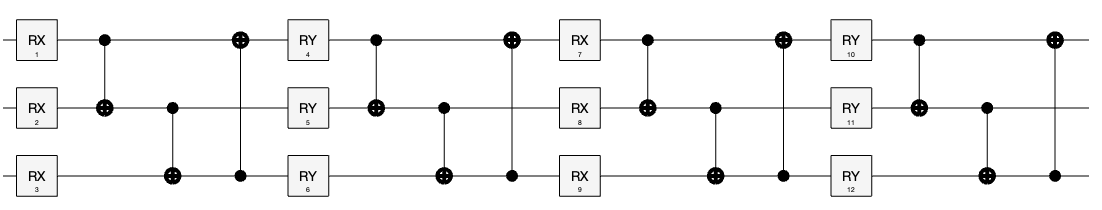

The output is then generated by measuring each qubit in the Z-basis. By measuring a qubit once we can only get $|0\rangle$ or $|1\rangle$ which is not informative enough, for this reason a real implementation should measure the qubits multiple times in order to get the expected value of the amplitudes of each state. For the pourpose of this example we are going to use directly the probability of measuring each qubit in each state.

The use of this quantum layer allows us to learn a highly expressive, nonlinear mapping between the input features and output classes, governed by quantum interference and entanglement rather than classical matrix operations.

#### Backpropagation

To train the network, the derivative of the loss function through the Quantum layer needs to be backpropagated.

Since quantum operations are non-differentiable we have to use the parameter-shift rule, which is a standard tecnique in variatinal quantum learning [5]. For each learnable parameter $\theta_i \;$the derivative is approximated as:


$$\frac{\partial L}{\partial \theta_i }\;\approx \;\frac{L\left(\theta_i +s\right)-L\left(\theta_i -s\right)}{2}$$


where $s=\frac{\pi }{4}$ is the shift constant.

#### Softmax Layer

The quantum layer outputs three scalar values, each derived from a qubit measurement. The `softmaxLayer` is necessary to convert them into a valid probability distribution across the three classes. This layer does not have trainable parameters, it simply applies the softmax transformation:


$$\textrm{softmax}\left(z_i \right)\;=\;\frac{e^{z_i } }{\sum_j e^{z_j } }$$


% net structure
layers = [
    featureInputLayer(4)
    QuantumLayer()
    softmaxLayer
];

we are gonna train the model with 50 epochs using the adam optimizer with a batch size of 25 and a learning rate of 0.01, also we are gonna shuffle the training data before each training epoch

% training options
options = trainingOptions("adam", ...
    MaxEpochs            = 50, ...
    MiniBatchSize        = 25, ...
    InitialLearnRate     = 1e-2, ...
    Shuffle              = "every-epoch", ...
    L2Regularization     = 1e-4, ...
    Plots                = "training-progress", ...
    ExecutionEnvironment = "cpu", ...
    Metrics              = "accuracy", ...
    Verbose              = false);


now we just have to train the model using cross-entroy loss.

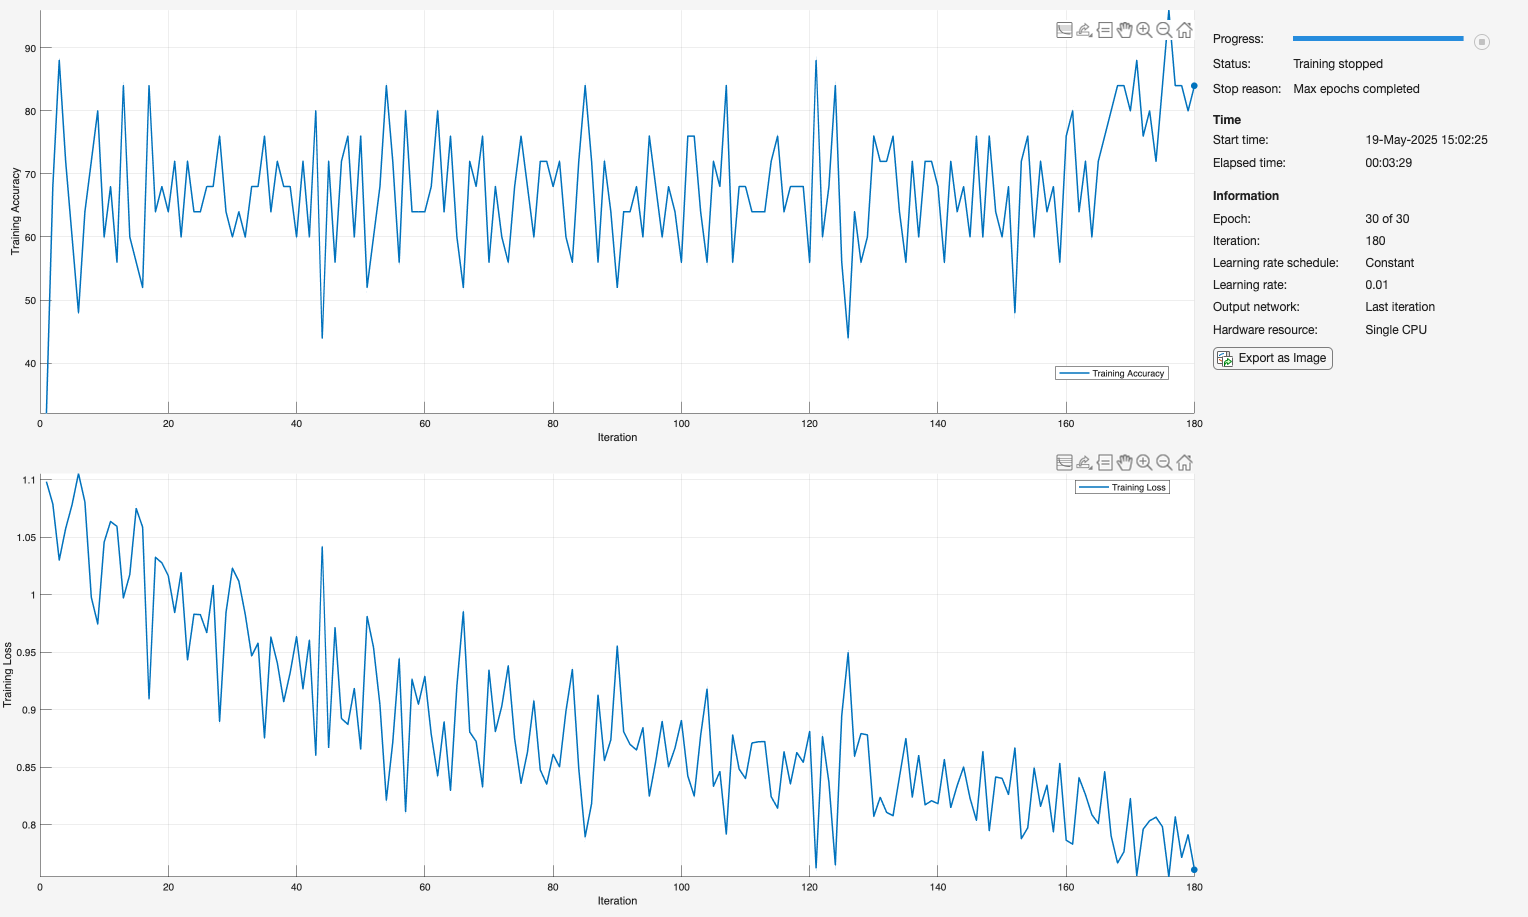

net = trainnet(X,Y,layers,"crossentropy",options);

XTest = X;
trueLabels = Y;
YTest = predict(net,XTest);

we should se an accuracy around 90%

accuracy = testnet(net,XTest,trueLabels,"accuracy")

accuracy = 87.3333

predictedLabels = scores2label(YTest, string(["Setosa", "Versicolar", "Virginica"]));

the result shoud show that the model identifies perfecty setosa while having some difficulties classifying versicolor and virginica. This is due to the fact that, as we said in the introduction, setosa is linearly separable from the other classes while versicolor and virginica have more complex non-linear boundaries, making them harder to tell apart.

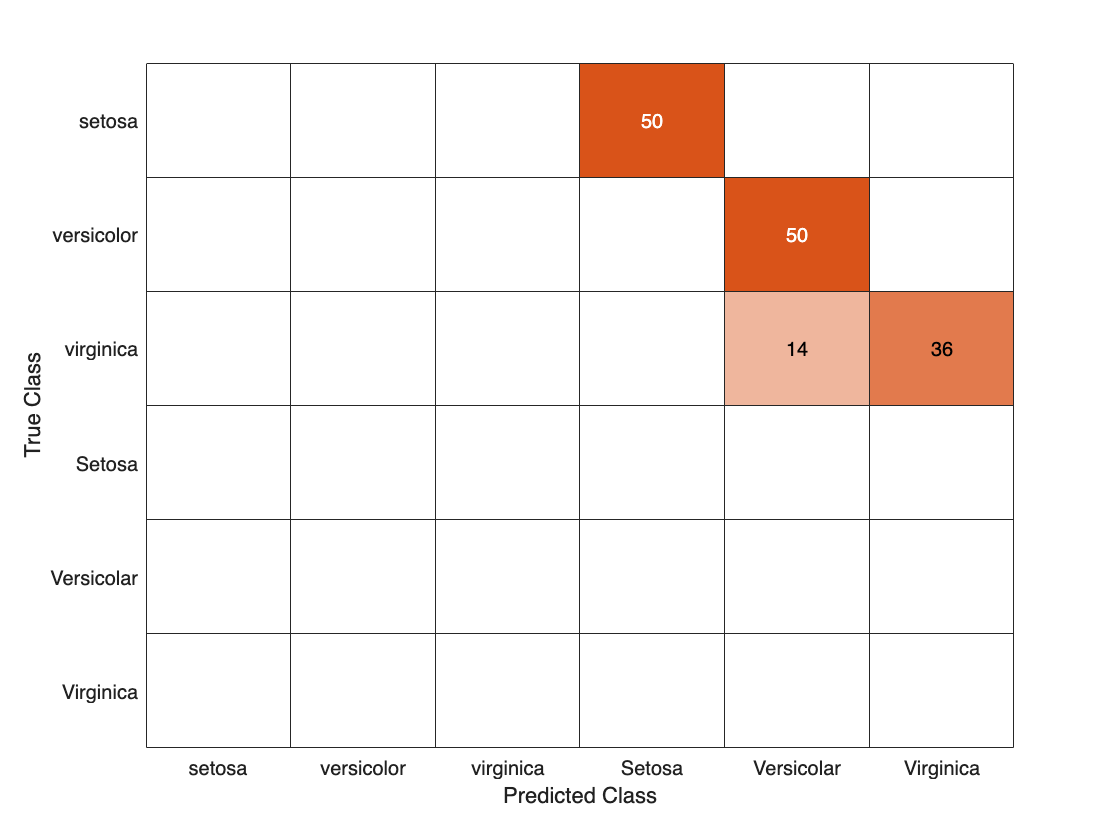

confusionchart(trueLabels,predictedLabels)

## References

[1] [J. Biamonte, P. Wittek, N. Pancotti, P. Rebentrost, N. Wiebe, S. Lloyd. "Quantum Machine Learning"](https://arxiv.org/abs/1611.09347)

[2] [H. Huang, M. Broughton, M. Mohseni, R. Babbush, S. Boixo, H. Neven, J. R. McClean. "Power of data in quantum machine learning"](https://arxiv.org/abs/2011.01938)

[3] [M. Fellous-Asiani,  J. H. Chai, R. S. Whitney, A Auffèves, H.K. Ng." Limitations in Quantum Computing from Resource Constraints"](https://arxiv.org/abs/2007.01966)

[4] [G. I. Correr, I. Medina, P. C. Azado, A. Drinko, D. O. Soares-Pinto. "Characterizing randomness in parameterized quantum circuits through expressibility and average entanglement"](https://arxiv.org/abs/2405.02265)

[5] [D. Wierichs, J. Izaac, C. Wang, C. Y Lin. "General parameter-shift rules for quantum gradients" ](https://arxiv.org/abs/2107.12390)